data = importdata("Assignment_Data_SC42145_2022.mat")

data = struct with fields:
           A: [5×5 double]
           B: [5×3 double]
           C: [2×5 double]
           D: [2×3 double]
         FWT: [2×3 ss]
    WindData: [60001×2 double]



A=data.A

A =    -0.4220   -0.2204         0   -0.2204         0
    0.0233   -0.0109   -0.0400   -0.0096         0
         0    1.0000         0         0         0
    0.1455   -0.0598         0   -0.1651  -10.8232
         0         0         0    1.0000         0


B=data.B

B =    -0.0799   -0.0096    0.2204
   -0.0067         0    0.0096
         0         0         0
   -0.0420         0    0.0598
         0         0         0


C=data.C

C =      1     0     0     0     0
     0     0     1     0     1


D=data.D

D =      0     0     0
     0     0     0


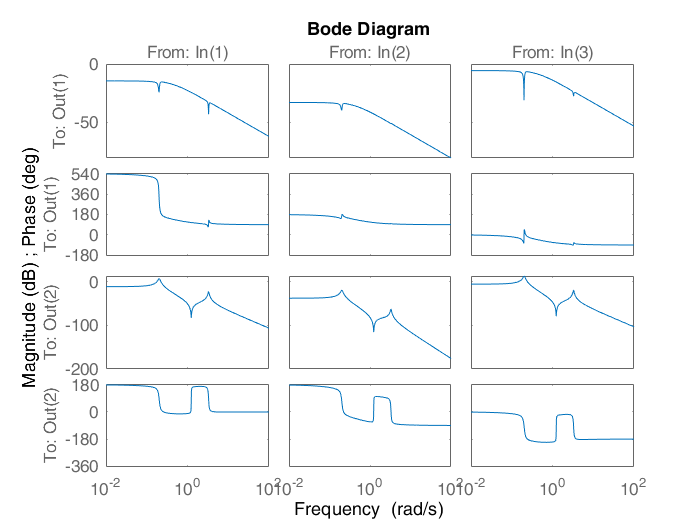

%print(data)
sys1 = ss(A,B,C,D);
bode(sys1)

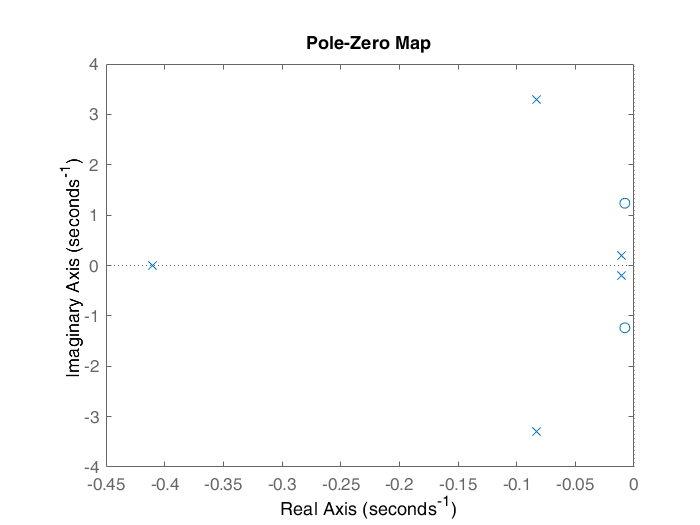

pzmap(sys1)